# **Effet d'une arthroplastie totale inversée d'épaule sur les synergies musculaires**

**Analyse synergies sujet par sujet pour un mouvement fonctionnel**

Paramètres

% 1) initializeParameters : regroupe tous les paramètres et configurations 
% tels que les muscles, les labels des tâches, le traitement de données, 
% l'assignation des tâches analytiques et la séparation des données en 3 cycles

Traitement des données

% 1) calculateMVC : calcul la contraction maximale volontaire pour le sujet
% et les muscles selon la tâche analytic assignée à chaque muscle en prenant 
% la moyenne des cinq valeurs les plus hautes du signal RMS analytic 
% (normalisation par une tâche sous-maximale standardisée)

% 2) processEMGSignal : traitement des données pour un muscle 

% 3) all_functional_data : traitement des données fonctionnelles pour un sujet

Calcul et assemblage des cycles 

% 1) detectMovementCycles: détecte les cycles en basant sur le marqueur
% RHLE (épicondyle latéral du coude)

% 2) identifyCycles : identifie les trois cycles pour chaque mouvement

% 3) mergeCycles : fusionne les cycles ensemble

Affichage des cycles 

% 1) plotCycleDetection : visualise la détection des cycles de mouvement

% 2) plotCycleSequence : visualise l'enchaînement des cycles pour tous les muscles

Affichage et sauvegarde de la matrice finale des données EMG traitées

% 1) saveDataMatrix : affiche et sauvegarde la matrice finale 

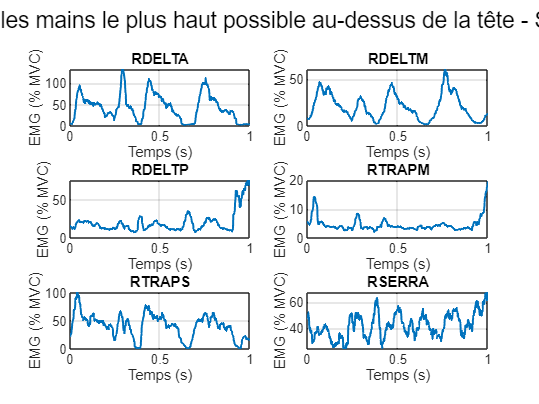

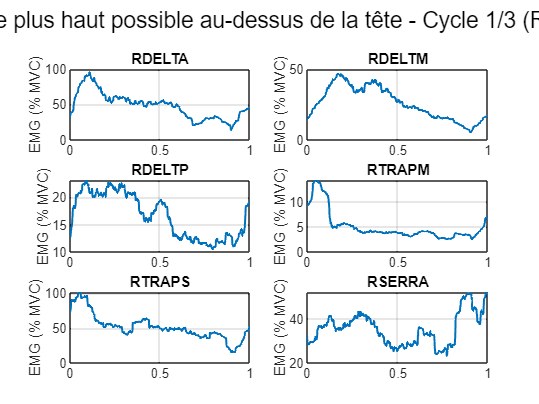

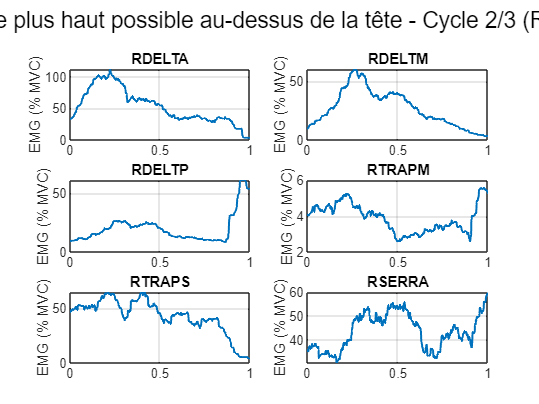

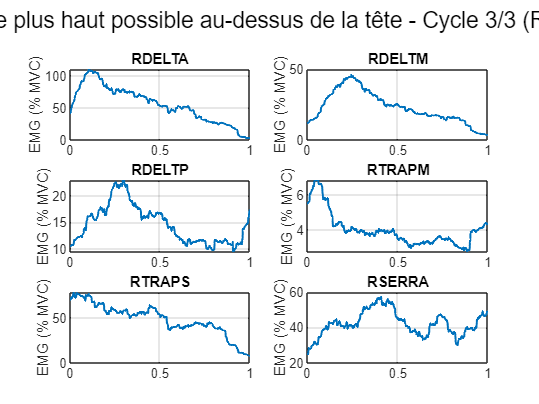

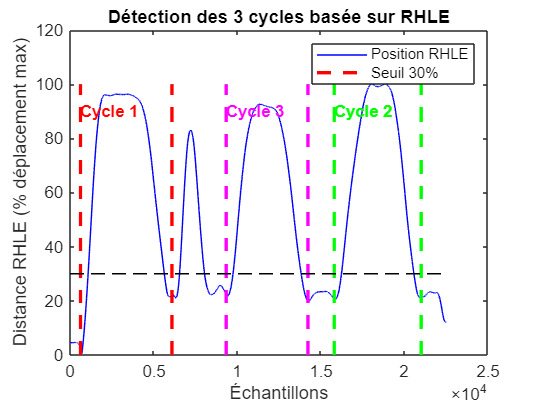

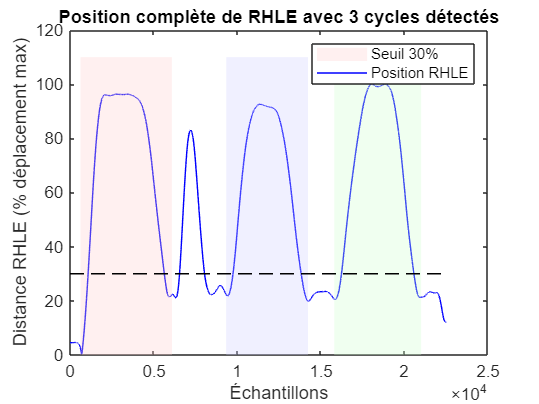

% Script principal d'analyse EMG
clc, clear all;

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition des paramètres
params = initializeParameters();

% Définition sujet 
subjects = {'AP22'}; % Marche pour un sujet
nb_subjects = length(subjects);
% 'MF01', 'TF02', 'YL03','SC04', 'RF05', 'AP06'
% 'TD07', 'IS08', 'LC09', 'MP10', 'PK11'
% 'TF12','JM13', 'GD14', 'LD15', 'LM16','NQ17', 'JV18'
% 'EG19', 'MG20', 'LB21', 'AP22', 'SC23'
% 'TM24', 'EG25', 'RL26'

% Calcul du MVC basé sur la tâche analytique assignée
mvc = calculateMVC(subjects, params);

% Sélection d'une tâche fonctionnelle unique
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Initialisation des données fonctionnelles
all_functional_data = cell(nb_subjects, params.nb_functional, params.nb_muscles, params.num_cycles);

% Traitement des données
for subj_idx = 1:nb_subjects
    all_functional_data = processFunctionalData(subjects{subj_idx}, selected_functional, mvc, params, all_functional_data, subj_idx);
end

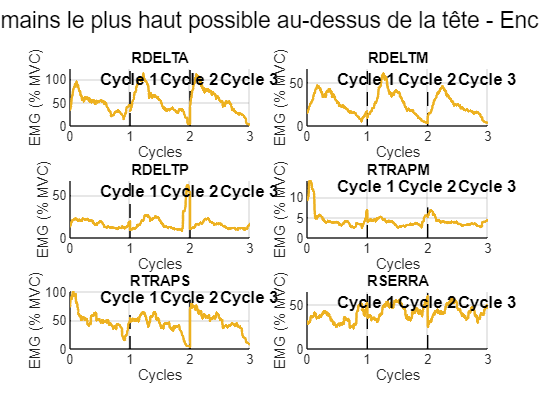


% Afficher l'enchaînement des cycles
plotCycleSequence(subjects, selected_functional, all_functional_data, params);


% Création et sauvegarde de la matrice de données
% saveDataMatrix(subjects{1}, selected_functional, all_functional_data, params);